**COT 5930 DIGITAL IMAGE PROCESSING**

**DR. HARI KALVA** 

**SPRING 2024**

**IAN MORGAN-GRAHAM**

**MATLAB ASSIGNMENT 1 - EXPANSION OF IMAGE TRAINING DATA SET THROUGH IMAGE PROCESSING/TRANSFORMATION**

**VERSION 2 - LIVESCRIPT CONTROLS**

**TABLE OF CONTENTS**

**SECTION 1: TASK A. READ IMAGES INTO A WORKSPACE VARIABLE**

**SECTION 2: TASK B. DISPLAY THE IMAGES**

**SECTION 3: TASK C. APPLY AN IMAGE PROCESSING FILTER/EFFECT OF YOUR CHOICE TO THE IMAGES**

**SECTION 4: TASK D. DISPLAY THE RESULTS**

**SECTION 5: TASK E. SAVE THE RESULTING IMAGES TO .PNG FILE FORMAT**

**SECTION 6: FUNCTIONS**

**SECTION 1: TASK A. READ IMAGES INTO A WORKSPACE VARIABLE**

SELECT AN IMAGE TO TRANSFORM THEN HIT "RUN" BUTTON AND CHECK "Output_Images" FOLDER

image_selected = ("/media/ijmg/SSD_FOUR_TB/ACADEMICS_101/a_Florida Atlantic University/MSOE/COT 5930 Dig Image Process/Assignment 1/betta.jpeg")  

image_selected = "/media/ijmg/SSD_FOUR_TB/ACADEMICS_101/a_Florida Atlantic University/MSOE/COT 5930 Dig Image Process/Assignment 1/betta.jpeg"

**SECTION 2: TASK B. DISPLAY THE IMAGES**

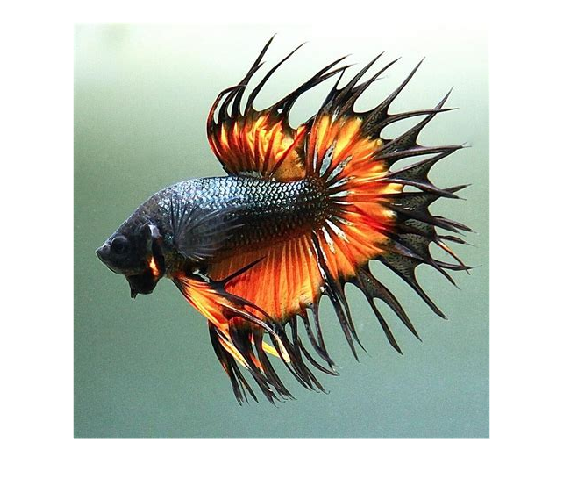

imshow(image_selected)

image_read = imread(image_selected);

**SECTION 3: TASK C. APPLY AN IMAGE PROCESSING FILTER/EFFECT OF YOUR CHOICE TO THE IMAGES**

transformed_image = {}


transformed_image =

  0×0 empty cell array



transformed_image = image_transformer(image_read)

transformed_image = 1×6 cell array
    {300×300×3 uint8}    {300×300×3 uint8}    {300×300×3 uint8}    {300×300×3 uint8}    {300×300×3 uint8}    {300×300×3 uint8}


**SECTION 4: TASK D. DISPLAY THE RESULTS**

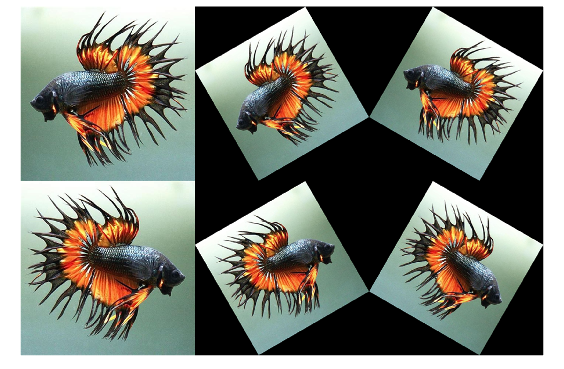

montage(transformed_image)

**SECTION 5: TASK E. SAVE THE RESULTING IMAGES TO .PNG FILE FORMAT**

species_name = erase(dir(image_selected).name, ".jpeg")

species_name = 'betta'

for pic_num = 1:length(transformed_image) 
   imwrite(transformed_image{pic_num},sprintf("./Output_Images/%s_%d.png",species_name,pic_num))
end

**SECTION 6: FUNCTIONS**

**FUNCTIONS**

Function to perform image transformations

function [transformed_array] = image_transformer(base_image)
    transformed_array = {};
    transformed_array{1} = imresize(base_image,[300 300]);
    transformed_array{2} = imresize(imrotate(base_image,30),[300 300]); 
    transformed_array{3} = imresize(imrotate(base_image,-30),[300 300]); 
    transformed_array{4} = imresize(flip(base_image,2),[300 300]); 
    transformed_array{5} = imresize(imrotate(flip(base_image,2),30),[300 300]); 
    transformed_array{6} = imresize(imrotate(flip(base_image,2),-30),[300 300]); 
end